# Matlab PMCSN

## Introduzione

Con questo live script da formalizzare a dovere viene provata la corrispondenza tra i valori analitici e quelli empirici trovati tramite la simulazione.

Il test viene effettuato con i seguenti parametri:


$$\begin{array}{l}
N_{\mathrm{server}} =3\\
\lambda_1 =6\\
\lambda_2 =6\ldotp 25\\
\mu {\;}_{1_{\mathrm{cloudlet}} } =0\ldotp 45\\
\mu {\;}_{2_{\mathrm{cloudlet}} } =0\ldotp 27\\
\mu {\;}_{1_{\mathrm{cloud}} } =0\ldotp 25\\
\mu {\;}_{2_{\mathrm{cloud}} } =0\ldotp 22
\end{array}$$


Siano arrivi e servizi di tasso esponenziale.

Il sistema è modellato nel seguente modo 

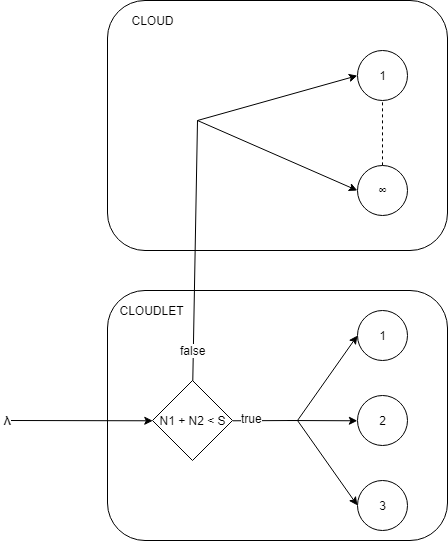

in particolare, da uno studio sulla catena di Markov relativa al solo sisema cloudlet si ha il seguente schema *scrivere anche il sistema di equazioni*

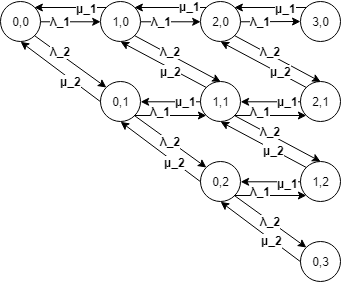

lambdaClassOne = 6;
lambdaClassTwo = 6.25;
cloudletMuClassOne = 0.45;
cloudletMuClassTwo = 0.27;
cloudMuClassOne = 0.25;
cloudMuClassTwo = 0.22;

Per prima cosa risolviamo la catena di markov relativa al sistema al fine di trovare il lambda entrante nel cloudlet e quello del cloud

lambda = lambdaClassOne + lambdaClassTwo;
[ploss, avgPopulationCloudlet] = plossCalculator;
fprintf('Probabilità di entrare nel cloudlet: \t%f \nprobabilità di entrare nel cloud: \t%f \nlambda entrante nel cloudlet: \t\t%f \nlambda entrante nel cloud: \t\t%f', vpa(1-ploss), vpa(ploss),vpa(lambda*(1-ploss)),vpa(lambda*ploss));

Probabilità di entrare nel cloudlet: 	0.079923 
probabilità di entrare nel cloud: 	0.920077 
lambda entrante nel cloudlet: 		0.979054 
lambda entrante nel cloud: 		11.270946

In questo caso si stanno considerando gli arrivi di prima e seconda classe come facenti parte dello stesso flusso. Analisi relative alla due singole classi saranno fatte successivamente.

I sistemi cloudlet e cloud non hanno coda. Questo vuol dire che un job che entra nel sistema deve essere immediatamente servito. In tal caso quindi i tempi di servizio dipendono fortemente dalla classe di appartenenza. Volendo scrivere quindi i tempi di servizio si ha che

PbeingClassOne = lambdaClassOne/lambda;
PbeingClassTwo = lambdaClassTwo/lambda;
cloudletServiceTimeClassOne = 1/cloudletMuClassOne;
cloudletServiceTimeClassTwo = 1/cloudletMuClassTwo;
cloudletST = PbeingClassOne*cloudletServiceTimeClassOne + ... 
             PbeingClassTwo*cloudletServiceTimeClassTwo;
cloudServiceTimeClassOne = 1/cloudMuClassOne;
cloudServiceTimeClassTwo = 1/cloudMuClassTwo;
cloudST =    PbeingClassOne*cloudServiceTimeClassOne + ... 
             PbeingClassTwo*cloudServiceTimeClassTwo;
globalST = ploss*cloudST + (1-ploss)*cloudletST;
classOneST = cloudletServiceTimeClassOne*(1-ploss) + ...
             cloudServiceTimeClassOne*(ploss);
classTwoST = cloudletServiceTimeClassTwo*(1-ploss) + ...
             cloudServiceTimeClassTwo*(ploss);
fprintf("Global Service time: \t\t\t%f\n" + ...
    "Global Service time cloudlet: \t\t%f \n" + ...
    "Global Service time cloud: \t\t%f\n" + ...
    "Global Service time class 1: \t\t%f\n" + ...
    "Global Service time class 2: \t\t%f\n" + ...
    "Service time cloudlet Class 1: \t\t%f\n" + ...
    "Service time cloudlet Class 2: \t\t%f\n" + ...
    "Service time cloud Class 1: \t\t%f\n" + ...
    "Service time cloud Class 2: \t\t%f", + ...
    globalST,cloudletST,classOneST,classTwoST,cloudletServiceTimeClassOne,cloudletServiceTimeClassTwo, + ...
    cloudletServiceTimeClassTwo,cloudServiceTimeClassOne,cloudServiceTimeClassTwo);

Global Service time: 			4.174376
Global Service time cloudlet: 		2.978080 
Global Service time cloud: 		3.857915
Global Service time class 1: 		4.478179
Global Service time class 2: 		2.222222
Service time cloudlet Class 1: 		3.703704
Service time cloudlet Class 2: 		3.703704
Service time cloud Class 1: 		4.000000
Service time cloud Class 2: 		4.545455

Come si può vedere dalla chiamata di funzione, plossCalculator permette di calcolare anche la media di popolazione all'interno del cloudlet. Per calcolare quella del cloud è sufficiente usare il teorema di Little

avgPopulationCloud = lambda*(ploss)*cloudST;
avgPopulationGlobal = avgPopulationCloud + avgPopulationCloudlet;
avgPopulationClassOne = avgPopulationGlobal*PbeingClassOne;
avgPopulationClassTwo = avgPopulationGlobal*PbeingClassTwo;

fprintf(['Popolazione media globale: \t\t%f\n' ...
    'Popolazione media cloudlet: \t\t%f\n' ...
    'Popolazione media cloud: \t\t%f\n' ...
    'Popolazione media classe 1: \t\t%f\n' ...
    'Popolazione media classe 2: \t\t%f\n' ...
    'Popolazione media cloudlet classe 1: \t%f\n' ...
    'Popolazione media cloudlet classe 2: \t%f\n' ...
    'Popolazione media cloud classe 1: \t%f\n' ...
    'Popolazione media cloud classe 2: \t%f'], + ...
    avgPopulationGlobal, avgPopulationCloudlet, avgPopulationCloud, avgPopulationClassOne, avgPopulationClassTwo, avgPopulationCloudlet*PbeingClassOne, + ...
    avgPopulationCloudlet*PbeingClassTwo, avgPopulationCloud*PbeingClassOne, avgPopulationCloud*PbeingClassTwo);

Popolazione media globale: 		51.136112
Popolazione media cloudlet: 		2.915702
Popolazione media cloud: 		48.220410
Popolazione media classe 1: 		25.046259
Popolazione media classe 2: 		26.089853
Popolazione media cloudlet classe 1: 	1.428099
Popolazione media cloudlet classe 2: 	1.487603
Popolazione media cloud classe 1: 	23.618160
Popolazione media cloud classe 2: 	24.602250

A Questo punto è possibile prendere in considerazione i valori della simulazione. In blu viene riportata la media calcolata empiricamente mentre in nero la media analitica

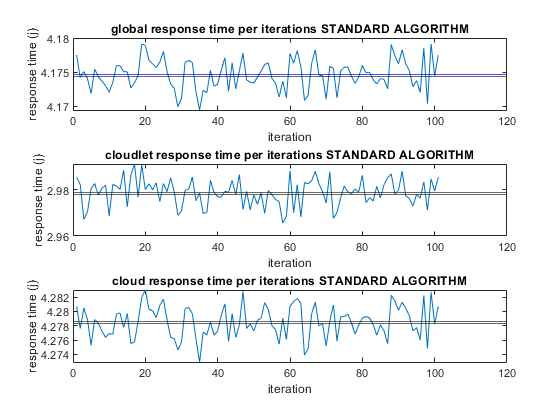

plotSteadyState(globalST, cloudletST, cloudST)

Supponiamo di voler sapere dopo quanto tempo raggiungono la media. Per questo motivo sono state salvati i valori relativi alle medie calcolate iterativamente relative ai primi mille pacchetti inviati

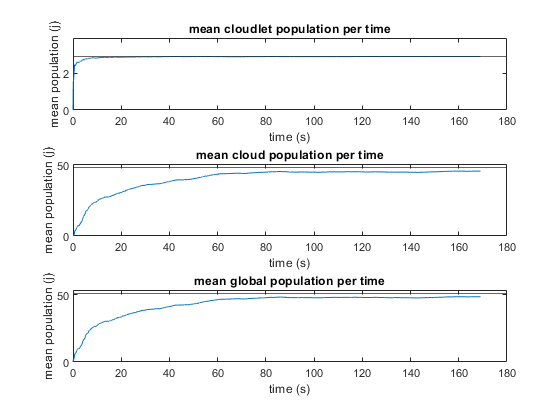

meansInOneSimulation(avgPopulationGlobal, avgPopulationCloudlet, avgPopulationCloud);

Per avere invece l'utilizzazione dei diversi server

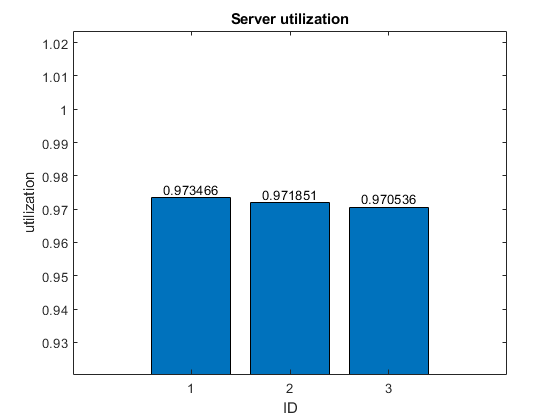

serverStatus;

Così come abbiamo fatto per i tempi di risposta, per stampare la media delle popolazioni attraverso le diverse iterazioni possiamo chiamare la seguente funzione

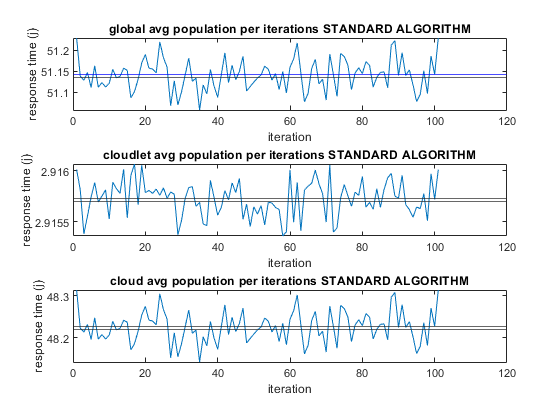

avgJobs(avgPopulationGlobal, avgPopulationCloudlet, avgPopulationCloud);